clc;
clear all;

% Choose modulation order and format
MOD_ORDER = 16;

MODULATION_FORMAT = 'QAM';

NUM_SYMBOLS_PER_CARRIER = 1e3;

NUM_SUBCARRIERS = 15;

CYCLIC_PREFIX_LENGTH = 1/8; % Given as a ratio of symbol length

OFDM_SYMBOL_LENGTH = ((2+2*NUM_SUBCARRIERS))*(1+CYCLIC_PREFIX_LENGTH);

assert(mod(OFDM_SYMBOL_LENGTH,1) == 0);

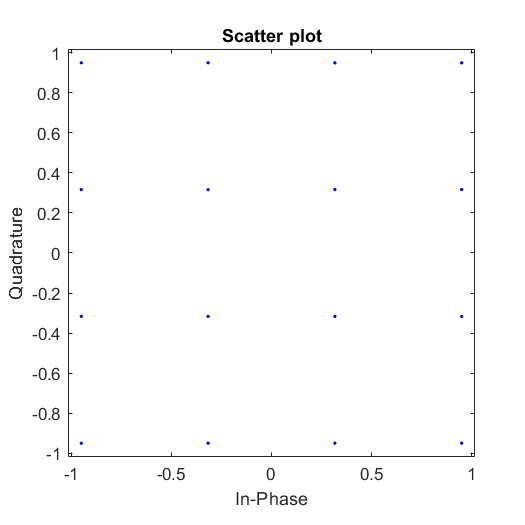

% Create QAM modulated signal, given number of symbols we want to generate

[modulated_signal, symbol_stream] = generateRandModSignal(NUM_SYMBOLS_PER_CARRIER, MOD_ORDER, NUM_SUBCARRIERS, MODULATION_FORMAT);
scatterplot(modulated_signal(:))

MOD_ORDER_VALS = [4; 16; 64]; % powers of 2 from 4 to 512

snr_ratios = linspace(1,25,50);
ber_vals = zeros(length(snr_ratios), length(MOD_ORDER_VALS));
normalised_snr_vals = zeros(length(snr_ratios), length(MOD_ORDER_VALS));

for mod_order_index = 1:1:length(MOD_ORDER_VALS)
    
    num_bits_per_symbol = log2(MOD_ORDER_VALS(mod_order_index));
    
    num_symbols_per_carrier = round((TOTAL_NUM_BITS/num_bits_per_symbol)/NUM_SUBCARRIERS);
    
    [modulated_signal, symbol_stream] = generateRandModSignal(num_symbols_per_carrier, MOD_ORDER_VALS(mod_order_index), NUM_SUBCARRIERS, MODULATION_FORMAT);
    
    ofdm_signal = convertToOFDMSignal(modulated_signal, CYCLIC_PREFIX_LENGTH);
    
    OFDM_SYMBOL_LENGTH = ((2+2*NUM_SUBCARRIERS))*(1+CYCLIC_PREFIX_LENGTH);
    
    normalised_snr_vals(:, mod_order_index) = normaliseSNR(num_bits_per_symbol, num_bits_per_symbol, snr_ratios);
    
    for snr_index = 1:1:length(snr_ratios)
        ofdm_signal_with_noise = awgn(ofdm_signal,snr_ratios(snr_index),'measured');
        extracted_modulated_signal = convertFromOFDMSignal(ofdm_signal, NUM_SUBCARRIERS, CYCLIC_PREFIX_LENGTH);
        extracted_modulated_signal_with_noise = awgn(extracted_modulated_signal, snr_ratios(snr_index), 'measured');
        extracted_stream = demodSignal(extracted_modulated_signal_with_noise, MOD_ORDER_VALS(mod_order_index), MODULATION_FORMAT);
        [num_bit_errors, ber_vals(snr_index, mod_order_index), num_symbol_errors, symbol_error_rate] = calculateErrorRates(extracted_stream, symbol_stream);
    end
end

Unrecognized function or variable 'TOTAL_NUM_BITS'.

ofdm_signal = convertToOFDMSignal(modulated_signal, CYCLIC_PREFIX_LENGTH);
ofdm_signal = awgn(ofdm_signal,15,'measured');
ofdm_signal - clipSignal(ofdm_signal, 1.5)
% histogram(ofdm_signal)


extracted_modulated_signal = convertFromOFDMSignal(ofdm_signal, NUM_SUBCARRIERS, CYCLIC_PREFIX_LENGTH);
scatterplot(extracted_modulated_signal(:))
extracted_stream = demodSignal(extracted_modulated_signal, MOD_ORDER, MODULATION_FORMAT);
[num_bit_errors, bit_error_rate, num_symbol_errors, symbol_error_rate] = calculateErrorRates(extracted_stream, symbol_stream)
